# KF Function Demo Fixed

% system clear

clc; clear all;



$$$$\textbf {KalMan Filter}$$
$$$$
$$Predict\ step:$$
$$ \quad{ \hat{\mathbf{x}}_{k\mid k-1} = \mathbf{F}_k \hat\mathbf{x}_{k-1\mid k-1} + \mathbf{B}_k \mathbf{u}_{k}} $$
$$ \quad{ {\mathbf{P}}_{k\mid k-1} = \mathbf{F}_k \mathbf{P}_{k-1 \mid k-1} \mathbf{F}_k^\textsf{T} + \mathbf{Q}_{k}} $$
$$Update\ step:$$
$$ \quad{ \mathbf{K}_k = {\mathbf{P}}_{k\mid k-1}\mathbf{H}_k^\textsf{T} {\left(\mathbf{H}_k {\mathbf{P}}_{k\mid k-1} \mathbf{H}_k^\textsf{T} + \mathbf{R}_k\right)}^{-1}} $$
$$ \quad{ \hat{\mathbf{x}}_{k\mid k} = \hat{\mathbf{x}}_{k\mid k-1} + \mathbf{K}_k{\left(\mathbf{z}_k - \mathbf{H}_k\hat{\mathbf{x}}_{k\mid k-1}\right)} $$
$$ \quad{ \mathbf{P}_{k|k} = \left(\mathbf{I} - \mathbf{K}_k \mathbf{H}_k\right) {\mathbf{P}}_{k|k-1}} $$$$


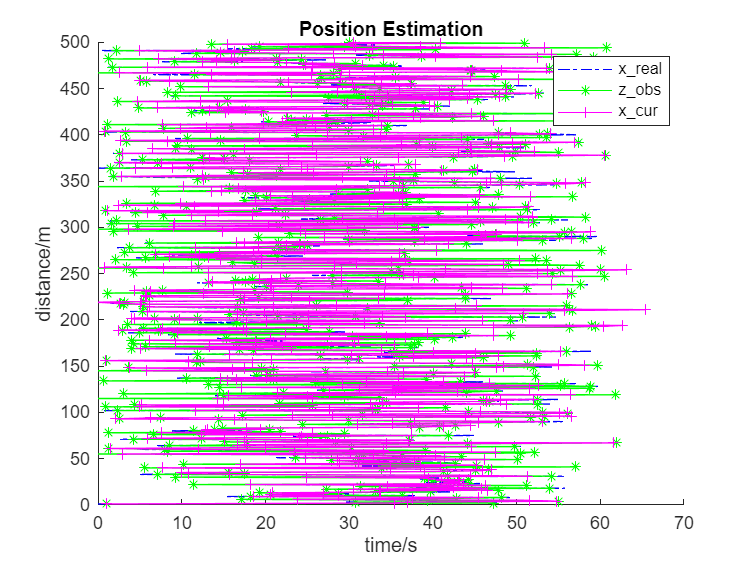


% step 0: config parameters
TEST_LEN = 500; % length for fixed
END_T = 50+10; % expand for fixed 
DELTA_T = 1;

LEN = length(1:DELTA_T:TEST_LEN);

fm = get_fimath();

% step 1: set init
mat_B = eye(2);
mat_F = [1 1; 0 1];

i_Q = .1;
i_R = 10;

k_cur = zeros(2,1,LEN);
x_cur = zeros(2,1,LEN);
p_cur = zeros(2,2,LEN);
k_cur_pos = zeros(1,1,LEN);

x_cur(:,:,1) = [0; 1];
p_cur(:,:,1) = eye(2).*10;

x_nxt = zeros(2,1,LEN);
p_nxt = zeros(2,2,LEN);

u = zeros(2,1,LEN);

x = zeros(2,1,LEN);
z = zeros(1,1,LEN);

% w = randn(2,1,LEN);
v = randn(1,1,LEN).*2;

% at the start, the speed is 1 and the position is 0
x(:,:,1) = [0 1];
for idx_i = 2:LEN
    x(:,:,idx_i) = 0 + (END_T).*rand(size(x(:,:,1)), "like", x(:,:,1));
end

z(1,:,1:LEN) = (x(1,:,1:LEN) + v(1,:,1:LEN));

% step 2: predict
% step 3: update
for idx_i = 1:LEN
    i_z(idx_i) = z(:,:,idx_i);
    i_Q(idx_i) = 0 + (10-0).*rand([1,1]);
    i_R(idx_i) = 0 + (10-0).*rand([1,1]);

    [o_x_cur, o_p_cur, o_k_cur_pos]= KF_Calc_SUnit_Fixed_S3(i_Q(idx_i), i_R(idx_i), i_z(idx_i));

    k_cur_pos(idx_i) = o_k_cur_pos;
    x_cur(:,:,idx_i) = o_x_cur;
    p_cur(:,:,idx_i) = o_p_cur;
end

save('KF_Calc_SUnit_Fixed_Src.m', "i_Q", "i_R", "i_z", "x", "k_cur_pos");

% step 4: disp
hold off; hold on;

axis([0 LEN 0 LEN]);
title('Position Estimation');
xlabel('time/s');
ylabel('distance/m');

y_plot(:) = (1:LEN);

x_plot(:) = x(1,1,:);
plot(x_plot, y_plot, 'b-.');

z_plot(:) = z(1,1,:);
plot(z_plot, y_plot, 'g-*');

x_cur_plot(:) = x_cur(1,1,:);
plot(x_cur_plot, y_plot, 'm-+');

xlim([0 70]);
ylim([0 500]);

legend('x\_real', 'z\_obs', 'x\_cur');


function fm = get_fimath()
    fm = fimath('RoundingMethod', 'Nearest',...
        'OverflowAction', 'Saturate',...
        'ProductMode','FullPrecision',...
        'SumMode','FullPrecision');
end
